clc; clear;

i = 1;
W = 150;
pho = 1.225;
v = [2:2:16]; %criando o vetor velocidade [primeiro termo, incrementa, ultimo termo]
s = 0.9; %area da asa

while i <= 8
    cl = (2*W)/(pho*(v(i)^2)*s);
    cd_0 = 0.022; %arrasto parasita
    cd_i = 0.065*(cl)^2; %arrasto induzido
    cd = cd_0 + cd_i;
    T_r = W/(cl/cd)
    i = i+1;
end

T_r = 663.3138

T_r = 166.0104

T_r = 74.1327

T_r = 42.2302

T_r = 27.7434

T_r = 20.1704

T_r = 15.9130

T_r = 13.4682

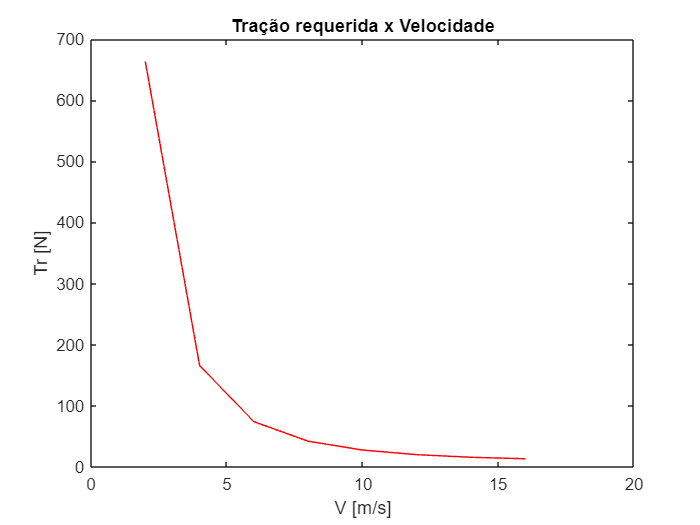


T = [663.3138 166.0104 74.1327 42.2302 27.7434 20.1704 15.9130 13.4682];
plot(v, T, 'Color', 'r');
title("Tração requerida x Velocidade");
xlabel("V [m/s]");
ylabel("Tr [N]");
xlim([0, 20]);
ylim([0, 700]);